g = 9.81;
m = 0.03;
R = 0.04

R = 0.0400

Jw = m*R^2/2;
M = 0.6;
W = 0.14;
D = 0.04;
H = 0.144;
L = H/2;
Jpsi = M*L^2/3;
Jphi = M*(W^2+D^2)/12;
Jm = 1e-5;
Rm = 6.69;
Kb = 0.468;
Kt = 0.317;
n = 1;
fm = 0.0022;
fm = ureal('fm', 0.0022,'Range',[0.001,0.005])

fm =   Uncertain real parameter "fm" with nominal value 0.0022 and range [0.001,0.005].


fw = 0.0001;
fw = ureal('fw', 0.0001,'Range',[0.00005,0.0002])

fw =   Uncertain real parameter "fw" with nominal value 0.0001 and range [5e-05,0.0002].


a = n*Kt/Rm;
b = n*Kt*Kb/Rm + fm;
s = b+fw;

e11 = (2*m+M)*R^2+2*Jw+2*Jm;
e12 = M*L*R-2*Jm;
e22 = M*L^2 + Jpsi + 2*Jm;

detE = e11*e22-e12^2;

a32 = -g*M*L*e12/detE;
a42 = g*M*L*e11/detE;
a33 = -2*(s*e22+b*e12)/detE;
a43 = 2*(s*e12+b*e11)/detE;
a34 = 2*b*(e22+e12)/detE;
a44 = -2*b*(e11+e12)/detE;
b3 = a*(e22 + e12)/detE;
b4 = -a*(e11+e12)/detE;

A = [0 0 1 0; 0 0 0 1; 0 a32 a33 a34;...
    0 a42 a43 a44];
B = [0 0; 0 0; b3 b3; b4 b4];

M = ss(A,B,eye(4),0)

M =

  Uncertain continuous-time state-space model with 4 outputs, 2 inputs, 4 states.
  The model uncertainty consists of the following blocks:
    fm: Uncertain real, nominal = 0.0022, range = [0.001,0.005], 1 occurrences
    fw: Uncertain real, nominal = 0.0001, range = [5e-05,0.0002], 1 occurrences

Type "M.NominalValue" to see the nominal value, "get(M)" to see all properties, and "M.Uncertainty" to interact with the uncertain elements.



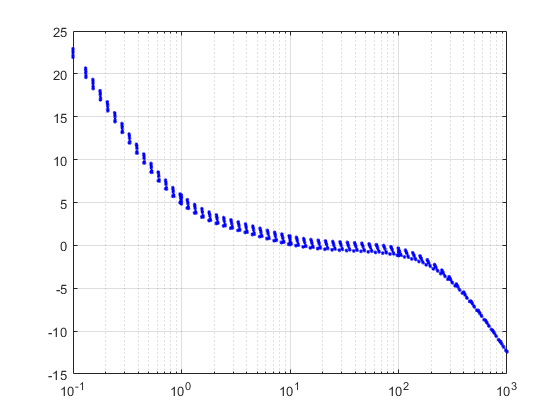

    figure;
for n=1:10
    [sig,w] = sigma(usample(M));

    semilogx(w,20*log10(sig(1,:)),'b.')
    hold on
    grid on
end


[G , D] = lftdata(M)

G =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3       0  -409.7  -162.6   162.1
   x4       0   269.6   78.34  -78.15
 
  B = 
            u1       u2       u3       u4
   x1        0        0        0        0
   x2        0        0        0        0
   x3   -3.773  -0.5395    157.6    157.6
   x4    1.819   0.2211   -75.96   -75.96
 
  C = 
           x1      x2      x3      x4
   y1       0       0   2.962  -2.962
   y2       0       0   0.583       0
   y3       1       0       0       0
   y4       0       1       0       0
   y5       0       0       1       0
   y6       0       0       0       1
 
  D = 
           u1      u2      u3      u4
   y1     0.4       0       0       0
   y2       0  0.3333       0       0
   y3       0       0       0       0
   y4       0       0       0       0
   y5       0       0       0       0
   y6       0       0       0       0
 
Continuous-time state-spac



s=tf('s');
Wp=[(0.57*s+0.95)/(2*s+0.024) 0 0 0 0;...
     0 0.9 0 0 0;...
     0 0 0.15 0 0;
     0 0 0 (0.242*s+0.22)/(s+1) 0;...
     0 0 0 0 (1.08*s+1.8)/(4*s+0.048)];
Wu=(0.06*s+0.04)/(0.0024*s+1)*eye(2);
Wn=[0.5*s+1 0;0 s+2]/(0.001*s+1);
int1=1/s;
G=M;
systemnames  = 'G Wp Wn Wu int1';
inputvar     = '[r{4}; n{2}; u{2}]';
outputvar    = '[Wp; Wu; r ;-G(1:2);-G(3:4)-Wn;int1 ]';
input_to_G   = '[u]';
input_to_int1 ='[r(1)-G(1)]';
input_to_Wp  = '[r-G; int1]';
input_to_Wu  = '[u]';
input_to_Wn =  '[n]';

P = minreal(sysic);

1 state removed.



ny=9;nu=2;
[Kinf,Ginf,gopt] = hinfsyn(P,ny,nu,'DISPLAY','on');


  Test bounds:  0.9 <=  gamma  <=  1.11

   gamma        X>=0        Y>=0       rho(XY)<1    p/f
  9.98e-01     0.0e+00     0.0e+00     3.090e-10     p
  9.48e-01     1.0e-17     0.0e+00     3.750e-10     p
  9.24e-01     0.0e+00     0.0e+00     4.257e-10     p
  9.12e-01     3.1e-22     0.0e+00     4.736e-10     p
  9.06e-01     4.4e-24     0.0e+00     5.397e-10     p

  Best performance (actual): 0.902


Kinf = minreal(ss(Kinf));

2 states removed.



Ginf = lft(P,Kinf);
w = logspace(-4,4,500);
[sig, w] = sigma(Ginf.NominalValue,w);


[Ninf, Del] = lftdata(Ginf);

Nrs = tf(Ninf);

Nrs = Nrs(1:2,1:2);

bndrs = mussv(frd(Nrs,w),[-1 0; -1 0]);

Points completed: 500/500




blkstr = [-1 0; -1 0; 6 7];
bnd = mussv(frd(Ninf,w),blkstr);

Points completed: 500/500


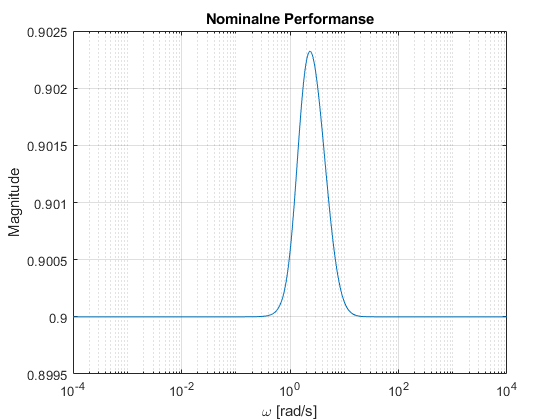


f_hinfnk = figure;

semilogx(w, sig(1,:))

xlabel('\omega [rad/s]')
ylabel("Magnitude")
title("Nominalne Performanse")
grid on

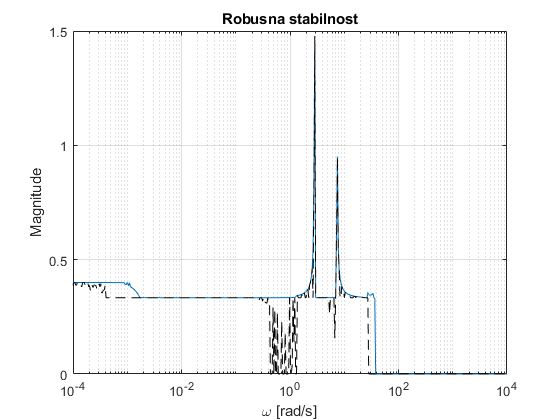


f_hinfrs = figure;
semilogx(w, squeeze(bndrs.ResponseData(1,1,:)))
hold on
semilogx(w, squeeze(bndrs.ResponseData(1,2,:)),'k--')
xlabel('\omega [rad/s]')
ylabel("Magnitude")
title("Robusna stabilnost")
grid on

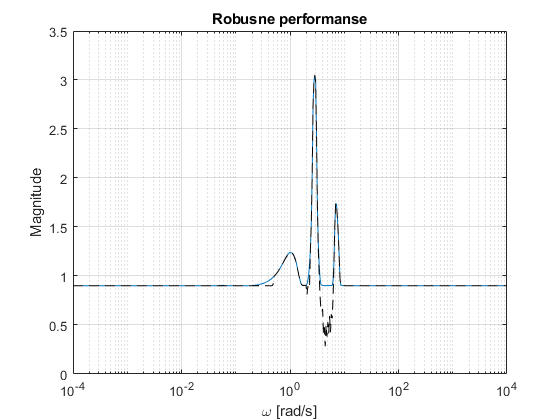


f_hinfmu = figure;
semilogx(w, squeeze(bnd.ResponseData(1,1,:)))
hold on
semilogx(w, squeeze(bnd.ResponseData(1,2,:)),'k--')
xlabel('\omega [rad/s]')
ylabel("Magnitude")
title("Robusne performanse")
grid on

 
 
 
Iteration Number:  1
--------------------
 

  Test bounds:  1.3 <=  gamma  <=  4.2

   gamma       X>=0        Y>=0       rho(XY)<1    p/f
  2.3e+00    -5.0e+02 #  -1.9e-13     3.903e-05     f
  Limiting gains...
  4.2e+00     0.0e+00     0.0e+00     5.980e-05     p
  4.2e+00     0.0e+00     0.0e+00     3.105e-04     p
  4.2e+00     0.0e+00     0.0e+00     7.538e-03     p
  4.2e+00     0.0e+00     0.0e+00     3.090e-01     p

  Best performance (actual): 3.5


Calculating MU of closed-loop system:
Points completed: 500/500
Points completed: 500/500


Iteration Summary            
-----------------------------
Iteration #                 1
Controller Order           11
Total D-Scale Order         0
Gamma Acheived          3.540
Peak mu-Value           3.374
 
Auto Fit in Progress 
	 Block 1, MaxOrder=5, Order = 0
 1
	 Block 2, MaxOrder=5, Order = 0
	 Block 3, MaxOrder=5, Order = 0


 
 
 
Iteration Number:  2
--------------------
 

  Test bounds:  0.9 <=  gamma  <=  1.9

   gamma       X>=0        Y>=0       rho(XY)<1    p/f
  1.3e+00     0.0e+00     0.0e+00     1.405e-04     p
  1.1e+00    -1.2e+02 #  -2.8e-14     1.254e-04     f
  1.2e+00    -6.8e+03 #  -7.1e-14     7.343e-05     f
  1.3e+00     0.0e+00     0.0e+00     2.211e-04     p
  Limiting gains...
  1.3e+00     0.0e+00     0.0e+00     9.166e-04     p
  1.3e+00     0.0e+00     2.2e-16     3.854e-03     p
  1.3e+00     0.0e+00     0.0e+00     5.001e-02     p
  1.3e+00    -7.5e-14    -1.2e-15     3.240e+00 #   f

  Best performance (actual): 1.3


Calculating MU of closed-loop system:
Points completed: 500/500
Points completed: 500/500


Iteration Summary                      
---------------------------------------
Iteration #                 1         2
Controller Order           11        13
Total D-Scale Order         0         2
Gamma Acheived          3.540     1.255
Peak mu-Value           3.374     1.253
 
Auto Fit in Progress 
	 Block 1, MaxOrder=5, Order = 0
 1
 2
	 Block 2, MaxOrder=5, Order = 0
	 Block 3, MaxOrder=5, Order = 0


 
 
 
Iteration Number:  3
--------------------
 

  Test bounds:  0.9 <=  gamma  <=  1.21

   gamma        X>=0        Y>=0       rho(XY)<1    p/f
  1.04e+00     0.0e+00     0.0e+00     3.521e-03     p
  9.69e-01     3.2e-16     0.0e+00     4.373e-03     p
  9.34e-01     0.0e+00     0.0e+00     4.952e-03     p
  9.17e-01     0.0e+00     0.0e+00     5.336e-03     p
  9.08e-01     0.0e+00     0.0e+00     5.632e-03     p
  Limiting gains...
  9.09e-01     0.0e+00     1.3e-16     1.054e-02     p
  9.09e-01     0.0e+00     0.0e+00     2.048e-02     p
  9.09e-01     0.0e+00     3.5e-15     8.528e-02     p
  9.09e-01     0.0e+00     0.0e+00     6.031e-01     p

  Best performance (actual): 0.904


Calculating MU of closed-loop system:
Points completed: 500/500
Points completed: 500/500


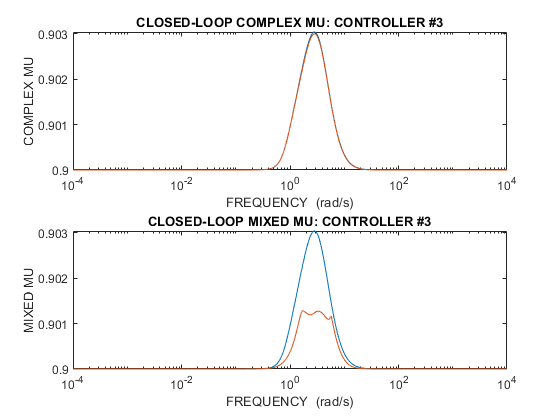

Iteration Summary                                
-------------------------------------------------
Iteration #                 1         2         3
Controller Order           11        13        15
Total D-Scale Order         0         2         4
Gamma Acheived          3.540     1.255     0.904
Peak mu-Value           3.374     1.253     0.903
 
 Next MU iteration number:  4


%mu optimalno DK
opt = dkitopt('FrequencyVector',w, ...
              'DisplayWhileAutoIter','on', ...
              'NumberOfAutoIterations',3);
[K_muopt,cl_mu,bnd_mu,dkinfo] = dksyn(P,ny,nu,opt);

K_muopt = minreal(ss(K_muopt));

3 states removed.


% zatvorena sprega
N = lft(P,K_muopt);
Nfrd = ufrd(N,w);
%% robusna stabilnost
opt = robopt('Display','on');
[stabmarg,destabu,report,info] = robuststab(Nfrd,opt);

Points completed: 500/500
ROBUSTSTAB Sensitivity calculations are beginning.
      Uncertain element fm...
      Uncertain element fw...


report

report = 7×101 char array
    'Assuming nominal UFRD system is stable...↵Uncertain system is robustly stable to modeled uncertainty.'
    ' -- It can tolerate up to 212% of the modeled uncertainty.                                           '
    ' -- There is a destabilizing perturbation amounting to 212% of the modeled uncertainty.              '
    ' -- This perturbation causes an instability at the frequency 4.98 rad/seconds.                       '
    ' -- Sensitivity with respect to each uncertain element is:                                           '
    '      100% for fm. Increasing fm by 25% decreases the margin by 25%.                                 '
    '      71% for fw. Increasing fw by 25% decreases the margin by 17.8%.                                '


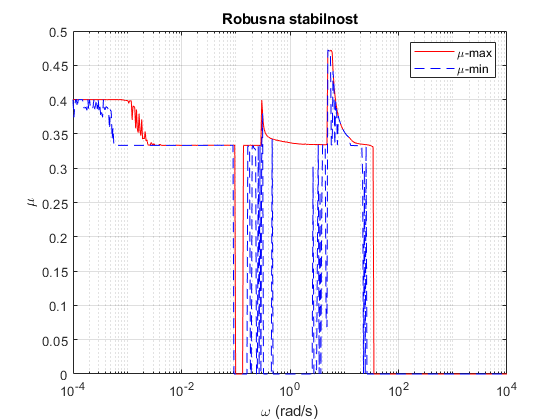

figure
semilogx(info.MussvBnds(1,1),'r-',info.MussvBnds(1,2),'b--')
grid
title('Robusna stabilnost')
xlabel('\omega (rad/s)')
ylabel('\mu')
legend('\mu-max','\mu-min')

%% robusne performanse
opt = robopt('Display','on');
[perfmarg,perfmargunc,report,info] = robustperf(Nfrd,opt);

Points completed: 500/500
ROBUSTSTAB Sensitivity calculations are beginning.
      Uncertain element fm...
      Uncertain element fw...


report

report = 6×114 char array
    'Assuming nominal UFRD system is stable...↵Uncertain system achieves performance robustness to modeled uncertainty.'
    ' -- The tradeoff of model uncertainty and system gain is balanced at a level of 111% of the modeled uncertainty.  '
    ' -- A model uncertainty of 111% can lead to input/output gain of 0.901 at 1.71 rad/seconds.                       '
    ' -- Sensitivity with respect to each uncertain element is:                                                        '
    '      1% for fm. Increasing fm by 25% decreases the margin by 0.25%.                                              '
    '      1% for fw. Increasing fw by 25% decreases the margin by 0.25%.                                              '


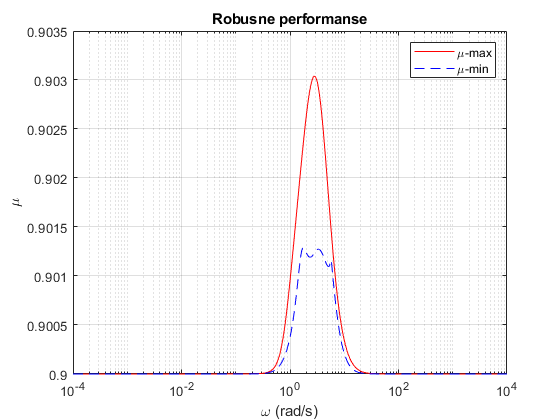

figure
semilogx(info.MussvBnds(1,1),'r-',info.MussvBnds(1,2),'b--')
grid
title('Robusne performanse')
xlabel('\omega (rad/s)')
ylabel('\mu')
legend('\mu-max','\mu-min')

%Fale nominalne performanse

Gmu = lft(P,K_muopt);
w = logspace(-4,4,500);
[sig_mu, w] = sigma(Gmu.NominalValue,w);


[Nmu, Del] = lftdata(Gmu);

Nrsmu = tf(Nmu);

Nrsmu = Nrsmu(1:2,1:2);

bndrsmu = mussv(frd(Nrsmu,w),[-1 0; -1 0]);

Points completed: 500/500




blkstr = [-1 0; -1 0; 6 7];
bndmu = mussv(frd(Nmu,w),blkstr);

Points completed: 500/500


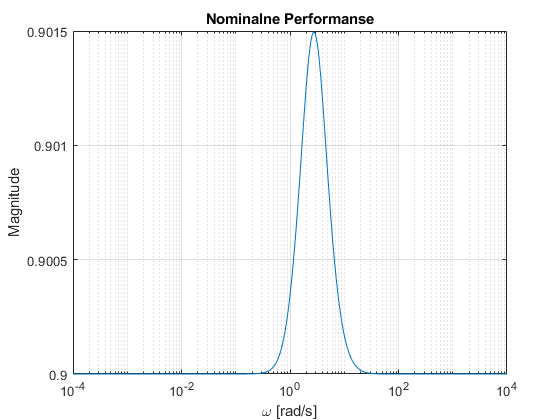

figure;

semilogx(w, sig_mu(1,:))

xlabel('\omega [rad/s]')
ylabel("Magnitude")
title("Nominalne Performanse")
grid on

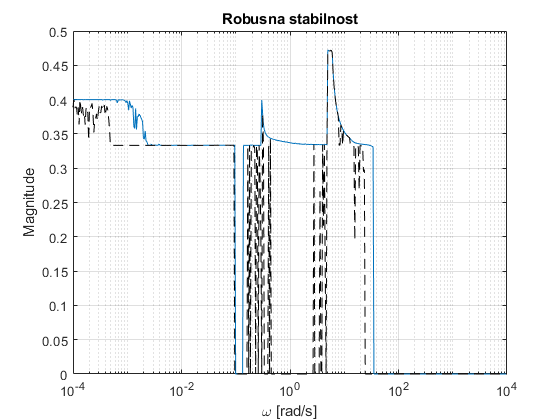


figure;
semilogx(w, squeeze(bndrsmu.ResponseData(1,1,:)))
hold on
semilogx(w, squeeze(bndrsmu.ResponseData(1,2,:)),'k--')
xlabel('\omega [rad/s]')
ylabel("Magnitude")
title("Robusna stabilnost")
grid on

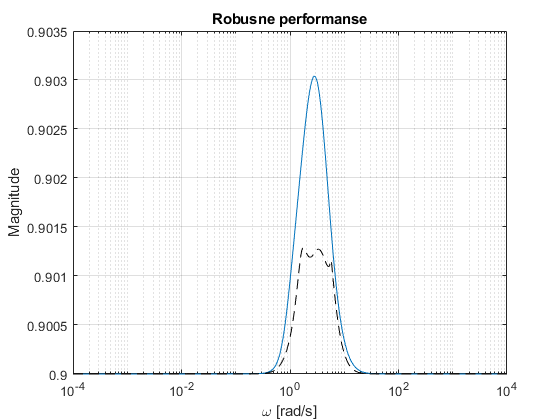


figure;
semilogx(w, squeeze(bndmu.ResponseData(1,1,:)))
hold on
semilogx(w, squeeze(bndmu.ResponseData(1,2,:)),'k--')
xlabel('\omega [rad/s]')
ylabel("Magnitude")
title("Robusne performanse")
grid on